# Predictive modeling using Auto Regression and tensor decompositions

## AR predictions on entire sum of signals vs SVD of sum of signals

clear all;
% Parameters
N = 100;  % Number of points in the time series
num_predict = 1;

% Some guess
L = floor((N-1) / 2);
num_experiments = 1;  % Number of experiments to perform

% Generate sinusoidal signals with optional exponential decay
t = (1:N)';
signal1 = sin(2 * pi * 0.1 * t) .* exp(-0.01 * t);
signal2 = sin(2 * pi * 0.05 * t) .* exp(-0.01 * t);
signal3 = sin(2 * pi * 0.02 * t) .* exp(-0.01 * t);

% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Ground truth for point 100
ground_truth = time_series(N);

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_components1 = zeros(num_experiments, 1);
predictions_components2 = zeros(num_experiments, 1);

% Add noise to the time series and perform the experiment
for exp = 1:num_experiments
    % Add noise
    noisy_series = time_series + randn(N, 1) * 0.1;  % Adjust noise level as needed

    training_range = noisy_series(1:end-num_predict);
    
    
    % Determine the optimal order for AR using the rank of the Hankel matrix as an estimate
    H2D = hankel(noisy_series(1:L),noisy_series(L:end));
    optimal_order = rank(H2D);

    % 1. Full time series prediction using AR model
    model_full = ar(noisy_series(1:N-1), optimal_order);  % AR(optimal_order) model
    pred_full = forecast(model_full, training_range, num_predict);
    predictions_full(exp) = pred_full(end);

    % 2. decomposition using partial hankel
    [U1, S1, V1] = svd(hankel(noisy_series(1:N-1)));
    num_components = 3;
    components1 = U1(:, 1:num_components) * S1(1:num_components, 1:num_components) * V1(:, 1:num_components)';

    % 3. Predict each component separately
    pred_components1 = zeros(num_components, 1);
    for comp = 1:num_components
        model_comp1 = ar(components1(:, comp), optimal_order);  % AR(optimal_order) model for each component
        pred_comp1 = forecast(model_comp1, components1(:, comp), num_predict);
        pred_components1(comp) = pred_comp1(end);
    end
    predictions_components1(exp) = sum(pred_components);


    % 2. decomposition using full hankel
    [U2, S2, V2] = svd(H2D);
    components2 = U2(:, 1:num_components) * S2(1:num_components, 1:num_components) * V2(:, 1:num_components)';

    % 3. Predict each component separately
    pred_components2 = zeros(num_components, 1);
    for comp = 1:num_components
        model_comp2 = ar(components2(:, comp), optimal_order);  % AR(optimal_order) model for each component
        pred_comp2 = forecast(model_comp2, components2(:, comp), num_predict);
        pred_components2(comp) = pred_comp2(end);
    end
    predictions_components2(exp) = sum(pred_components);
end

Error using ar
There are too many parameters to estimate for chosen estimation data size. Reduce model order or use a larger data set.


% Compare predictions
figure;
subplot(3, 1, 1);
histogram(predictions_full);
title('Predictions from Full Time Series');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line

subplot(3, 1, 2);
histogram(predictions_components1);
title('Predictions from Component Decomposition 1');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line

subplot(3, 1, 3);
histogram(predictions_components2);
title('Predictions from Component Decomposition 2');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line

% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');
disp(['Mean: ', num2str(mean(predictions_full)), ', Std: ', num2str(std(predictions_full))]);

disp('Component Decomposition Predictions 1:');
disp(['Mean: ', num2str(mean(predictions_components1)), ', Std: ', num2str(std(predictions_components1))]);

disp('Component Decomposition Predictions 2:');
disp(['Mean: ', num2str(mean(predictions_components2)), ', Std: ', num2str(std(predictions_components2))]);



## DEBUGGING

clear all;
% Parameters
N = 430;  % Number of points in the time series
num_predict = 1;
L = floor((N-1) / 2);
num_experiments = 1;  % Number of experiments to perform

% Generate sinusoidal signals with optional exponential decay
t = (1:N)';
signal1 = 10*sin(2 * pi * 0.1 * t);
signal2 = 10*sin(2 * pi * 0.05 * t);
signal3 = 10*sin(2 * pi * 0.02 * t);

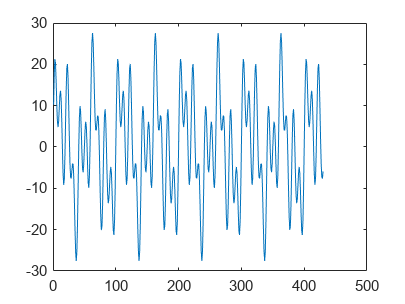


% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;
%figure;
%plot(time_series);
%time_series = time_series - time_series(1)

figure;
plot(time_series);


% Ground truth for point 100
ground_truth = time_series(N);

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_components1 = zeros(num_experiments, 1);
predictions_components2 = zeros(num_experiments, 1);

% Add noise to the time series and perform the experiment
for exp = 1:num_experiments
    % Add noise
    noisy_series = time_series;% + randn(N, 1) * 0.1;  % Adjust noise level as needed

    training_range = noisy_series(1:N-num_predict);
    
    % Determine the optimal order for AR using the rank of the Hankel matrix as an estimate
    H2D = hankel(noisy_series(1:L), noisy_series(L:end-1));
    optimal_order = 4;

    % 1. Full time series prediction using AR model
    model_full = ar(noisy_series(1:N-1), optimal_order);  % AR(optimal_order) model
    pred_full = forecast(model_full, training_range, num_predict);
    predictions_full(exp) = pred_full(end);

    H2Dzeros = hankel(noisy_series(1:N-1));

    % 2. decomposition using partial hankel
    [U1, S1, V1] = svd(H2Dzeros, 'econ');
    num_components = 3;
    components1 = U1(:, 1:num_components) * S1(1:num_components, 1:num_components) * V1(:, 1:num_components)';

    % 3. Predict each component separately
    pred_components1 = zeros(num_components, 1);
    for comp = 1:num_components
        components1(:, comp)
        model_comp1 = ar(components1(:, comp), optimal_order);  % AR(optimal_order) model for each component
        pred_comp1 = forecast(model_comp1, components1(:, comp), num_predict);
        pred_components1(comp) = pred_comp1(end);
    end

    predictions_components1(exp) = sum(pred_components1);


    % 2. decomposition using full hankel
    [U2, S2, V2] = svd(H2D, 'econ');
    components2 = U2(:, 1:num_components) * S2(1:num_components, 1:num_components) * V2(:, 1:num_components)';

    % 3. Predict each component separately
    pred_components2 = zeros(num_components, 1);
    for comp = 1:num_components
        model_comp2 = ar(components2(:, comp), optimal_order);  % AR(optimal_order) model for each component
        pred_comp2 = forecast(model_comp2, components2(:, comp), num_predict);
        pred_components2(comp) = pred_comp2(end);
    end
    predictions_components2(exp) = sum(pred_components2);
end

ans =    24.5709
   29.2597
   28.5282
   22.9648
   14.7113
    6.6574
    1.3728
    0.1801
    2.7174
    7.1516


ans =    29.2597
   30.8265
   26.8659
   19.4023
   11.4683
    5.9483
    4.5044
    6.9944
   11.5965
   15.5874


ans =    28.5282
   26.8659
   21.3699
   14.8106
   10.0147
    8.7771
   11.1956
   15.6823
   19.6398
   20.5390


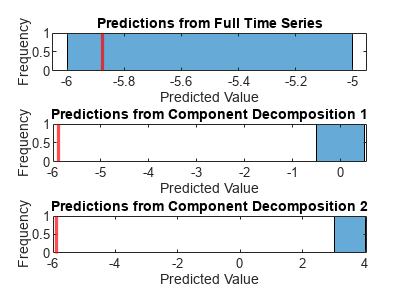


% Compare predictions
figure;
subplot(3, 1, 1);
histogram(predictions_full);
title('Predictions from Full Time Series');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line

subplot(3, 1, 2);
histogram(predictions_components1);
title('Predictions from Component Decomposition 1');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line

subplot(3, 1, 3);
histogram(predictions_components2);
title('Predictions from Component Decomposition 2');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line


% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp(['Mean: ', num2str(mean(predictions_full)), ', Std: ', num2str(std(predictions_full))]);

Mean: -5.7031, Std: 0



disp('Component Decomposition Predictions 1:');

Component Decomposition Predictions 1:


disp(['Mean: ', num2str(mean(predictions_components1)), ', Std: ', num2str(std(predictions_components1))]);

Mean: -0.075197, Std: 0



disp('Component Decomposition Predictions 2:');

Component Decomposition Predictions 2:


disp(['Mean: ', num2str(mean(predictions_components2)), ', Std: ', num2str(std(predictions_components2))])

Mean: 3.4543, Std: 0


## AR predictions on entire sum of signals vs CPD of sum of signals 

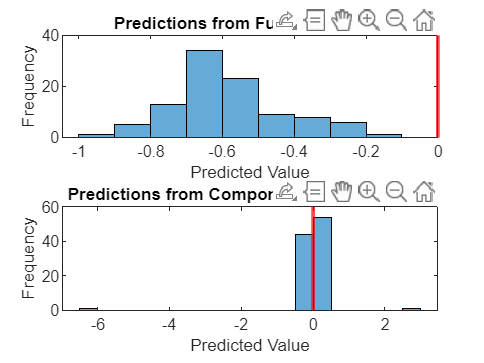


clear all;
addpath('./tensorlab');  % Ensure Tensorlab is in your path
addpath('./cvx');  % Ensure CVX is in your path

% Parameters
N = 100;  % Number of points in the time series
L = 20;   % Number of rows in each Hankel matrix
num_series = 3;  % Number of sinusoidal signals
num_experiments = 100;  % Number of experiments to perform
rank = 3;  % Rank for the CP decomposition

% Generate sinusoidal signals with optional exponential decay
t = (1:N)';
signal1 = sin(2 * pi * 0.1 * t) .* exp(-0.01 * t);
signal2 = sin(2 * pi * 0.05 * t) .* exp(-0.01 * t);
signal3 = sin(2 * pi * 0.02 * t) .* exp(-0.01 * t);

% Combine signals to form the time series matrix
time_series_matrix = [signal1, signal2, signal3];

% Ground truth for point 100
ground_truth = sum(time_series_matrix(N, :));

% Prepare storage for predictions
predictions_full = zeros(num_experiments,1);
predictions_matrix_components = zeros(num_experiments,1);
predictions_tensor_components = zeros(num_experiments,1);

% Define options for CPD
options = struct;
options.Display = 0;  % Turn off display

% Add noise to the time series and perform the experiment
for exp = 1:num_experiments
    % Add noise
    noisy_tensor = time_series_matrix + randn(size(time_series_matrix)) * 0.1;  % Adjust noise level as needed

    % Full time series prediction using AR model for each series
    pred_full_sum = 0;
    for i = 1:num_series
        data = iddata(noisy_tensor(1:N-1, i), [], 1);
        ar_model = ar(data, 1);
        pred_full = predict(ar_model, data, 1);
        pred_full_sum = pred_full_sum + pred_full.OutputData(end);
    end
    predictions_full(exp) = pred_full_sum;

    % Construct 3D Hankel tensor
    H3D = zeros(L, N-L+1, num_series);
    for i = 1:num_series
        H2D = hankel(noisy_tensor(1:L, i), noisy_tensor(L:N, i));
        H3D(:, :, i) = H2D;
    end

    % Perform CP decomposition using Tensorlab
    cp_decomp = cpd(H3D, rank, options);

    % Predict each component separately
    pred_components_sum = 0;
    for comp = 1:rank
        component_data = iddata(cp_decomp{1}(:, comp), [], 1);
        ar_model_comp = ar(component_data, 1);
        pred_comp = predict(ar_model_comp, component_data, 1);
        pred_components_sum = pred_components_sum + pred_comp.OutputData(end);
    end
    predictions_components(exp) = pred_components_sum;
end

% Compare predictions
figure;
subplot(2, 1, 1);
histogram(predictions_full);
title('Predictions from Full Time Series');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line

subplot(2, 1, 2);
histogram(predictions_components);
title('Predictions from Component Decomposition');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line


% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp(['Mean: ', num2str(mean(predictions_full)), ', Std: ', num2str(std(predictions_full))]);

Mean: -0.58328, Std: 0.15471



disp('Component Decomposition Predictions:');

Component Decomposition Predictions:


disp(['Mean: ', num2str(mean(predictions_components)), ', Std: ', num2str(std(predictions_components))]);

Mean: -0.010258, Std: 0.72065


## All methods combined, tryouts 1

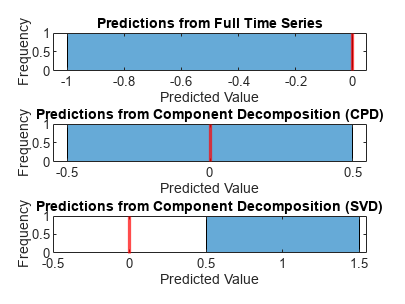


clear all;
addpath('./tensorlab');  % Ensure Tensorlab is in your path
addpath('./cvx');  % Ensure CVX is in your path

% Parameters
N = 100;  % Number of points in the time series
L = 20;   % Number of rows in each Hankel matrix
num_series = 3;  % Number of sinusoidal signals
num_experiments = 1;  % Number of experiments to perform
rank = 3;  % Rank for the CP decomposition

% Generate sinusoidal signals with optional exponential decay
t = (1:N)';
signal1 = sin(2 * pi * 0.1 * t) .* exp(-0.01 * t);
signal2 = sin(2 * pi * 0.05 * t) .* exp(-0.01 * t);
signal3 = sin(2 * pi * 0.02 * t) .* exp(-0.01 * t);

% Combine signals to form the time series matrix
time_series_matrix = [signal1, signal2, signal3];

% Ground truth for point 100
ground_truth = sum(time_series_matrix(N, :));

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_components_cpd = zeros(num_experiments, 1);
predictions_components_svd = zeros(num_experiments, 1);

% Define options for CPD
options = struct;
options.Display = 0;  % Turn off display

% Add noise to the time series and perform the experiment
for exp = 1:num_experiments
    % Add noise
    noisy_tensor = time_series_matrix + randn(size(time_series_matrix)) * 0.1;  % Adjust noise level as needed

    % Full time series prediction using AR model for each series
    pred_full_sum = 0;
    for i = 1:num_series
        data = iddata(noisy_tensor(1:N-1, i), [], 1);
        ar_model = ar(data, 1);
        pred_full = predict(ar_model, data, 1);
        pred_full_sum = pred_full_sum + pred_full.OutputData(end);
    end
    predictions_full(exp) = pred_full_sum;

    % Construct 3D Hankel tensor
    H3D = zeros(L, N-L+1, num_series);
    for i = 1:num_series
        H2D = hankel(noisy_tensor(1:L, i), noisy_tensor(L:N, i));
        H3D(:, :, i) = H2D;
    end

    % Perform CP decomposition using Tensorlab
    cp_decomp = cpd(H3D, rank, options);

    % Predict each component separately using CPD
    pred_components_cpd_sum = 0;
    for comp = 1:rank
        component_data = iddata(cp_decomp{1}(:, comp), [], 1);
        ar_model_comp = ar(component_data, 1);
        pred_comp = predict(ar_model_comp, component_data, 1);
        pred_components_cpd_sum = pred_components_cpd_sum + pred_comp.OutputData(end);
    end
    predictions_components_cpd(exp) = pred_components_cpd_sum;

    % Perform SVD on each noisy time series
    pred_components_svd_sum = 0;
    for i = 1:num_series
        H2D = hankel(noisy_tensor(1:L, i), noisy_tensor(L:N, i));
        [U, S, V] = svd(H2D, 'econ');
        num_components = rank;  % Use the same number of components as CPD
        components = U(:, 1:num_components) * S(1:num_components, 1:num_components) * V(:, 1:num_components)';
        
        % Predict each component separately using SVD
        for j = 1:num_components
            component_data = iddata(components(:, j), [], 1);
            ar_model_comp = ar(component_data, 1);
            pred_comp = predict(ar_model_comp, component_data, 1);
            pred_components_svd_sum = pred_components_svd_sum + pred_comp.OutputData(end);
        end
    end
    predictions_components_svd(exp) = pred_components_svd_sum;
end

% Compare predictions
figure;
subplot(3, 1, 1);
histogram(predictions_full);
title('Predictions from Full Time Series');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line

subplot(3, 1, 2);
histogram(predictions_components_cpd);
title('Predictions from Component Decomposition (CPD)');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line

subplot(3, 1, 3);
histogram(predictions_components_svd);
title('Predictions from Component Decomposition (SVD)');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2);  % Ground truth line


% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp(['Mean: ', num2str(mean(predictions_full)), ', Std: ', num2str(std(predictions_full))]);

Mean: -0.63942, Std: 0



disp('Component Decomposition Predictions (CPD):');

Component Decomposition Predictions (CPD):


disp(['Mean: ', num2str(mean(predictions_components_cpd)), ', Std: ', num2str(std(predictions_components_cpd))]);

Mean: 0.05322, Std: 0



disp('Component Decomposition Predictions (SVD):');

Component Decomposition Predictions (SVD):


disp(['Mean: ', num2str(mean(predictions_components_svd)), ', Std: ', num2str(std(predictions_components_svd))]);

Mean: 1.1989, Std: 0


## All methods combined in one histogram figure


clear all;
addpath('./tensorlab');  % Ensure Tensorlab is in your path
addpath('./cvx');  % Ensure CVX is in your path

% Parameters
N = 100;  % Number of points in the time series
L = 20;   % Number of rows in each Hankel matrix
num_series = 3;  % Number of sinusoidal signals
num_experiments = 10;  % Number of experiments to perform
rank = 3;  % Rank for the CP decomposition

% Generate sinusoidal signals with optional exponential decay
t = (1:N)';
signal1 = sin(2 * pi * 0.1 * t) .* exp(-0.01 * t);
signal2 = sin(2 * pi * 0.05 * t) .* exp(-0.01 * t);
signal3 = sin(2 * pi * 0.02 * t) .* exp(-0.01 * t);

% Combine signals to form the time series matrix
time_series_matrix = [signal1, signal2, signal3];

% Ground truth for point 100
ground_truth = sum(time_series_matrix(N, :));

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_components_svd = zeros(num_experiments, 1);
predictions_components_cpd = zeros(num_experiments, 1);

% Define options for CPD
options = struct;
options.Display = 0;  % Turn off display

% Add noise to the time series and perform the experiment
for exp = 1:num_experiments
    % Add noise
    noisy_tensor = time_series_matrix;% + randn(size(time_series_matrix)) * 0.1;  % Adjust noise level as needed

    % Full time series prediction using AR model for each series
    pred_full_sum = 0;
    for i = 1:num_series
        data = iddata(noisy_tensor(1:N-1, i), [], 1);
        ar_model = ar(data, 1);
        pred_full = predict(ar_model, data, 1);
        pred_full_sum = pred_full_sum + pred_full.OutputData(end);
    end
    predictions_full(exp) = pred_full_sum;

    % Perform SVD on each noisy time series
    pred_components_svd_sum = 0;
    for i = 1:num_series
        H2D = hankel(noisy_tensor(1:L, i), noisy_tensor(L:N, i));
        [U, S, V] = svd(H2D, 'econ');
        num_components = rank;  % Use the same number of components as CPD
        components = U(:, 1:num_components) * S(1:num_components, 1:num_components) * V(:, 1:num_components)';
        
        % Predict each component separately using SVD
        for j = 1:num_components
            component_data = iddata(components(:, j), [], 1);
            ar_model_comp = ar(component_data, 1);
            pred_comp = predict(ar_model_comp, component_data, 1);
            pred_components_svd_sum = pred_components_svd_sum + pred_comp.OutputData(end);
        end
    end
    predictions_components_svd(exp) = pred_components_svd_sum;

    % Construct 3D Hankel tensor
    H3D = zeros(L, N-L+1, num_series);
    for i = 1:num_series
        H2D = hankel(noisy_tensor(1:L, i), noisy_tensor(L:N, i));
        H3D(:, :, i) = H2D;
    end

    % Perform CP decomposition using Tensorlab
    cp_decomp = cpd(H3D, rank, options);

    % Predict each component separately using CPD
    pred_components_cpd_sum = 0;
    for comp = 1:rank
        component_data = iddata(cp_decomp{1}(:, comp), [], 1);
        ar_model_comp = ar(component_data, 1);
        pred_comp = predict(ar_model_comp, component_data, 1);
        pred_components_cpd_sum = pred_components_cpd_sum + pred_comp.OutputData(end);
    end
    predictions_components_cpd(exp) = pred_components_cpd_sum;
end


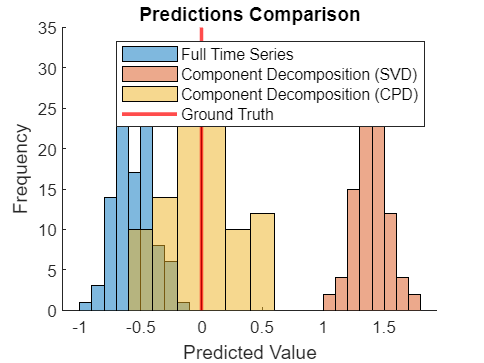

% Compare predictions
figure;
hold on;
histogram(predictions_full, 'FaceAlpha', 0.5, 'DisplayName', 'Full Time Series');
histogram(predictions_components_svd, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (SVD)');
histogram(predictions_components_cpd, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (CPD)');
title('Predictions Comparison');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2, 'DisplayName', 'Ground Truth');  % Ground truth line
legend;
hold off;



% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp(['Median: ', num2str(median(predictions_full)), ' Mean: ', num2str(mean(predictions_full)), ', Std: ', num2str(std(predictions_full))]);

Median: -0.59431 Mean: -0.59431, Std: 1.1703e-16



disp('Component Decomposition Predictions (SVD):');

Component Decomposition Predictions (SVD):


disp(['Median: ', num2str(median(predictions_components_svd)), ' Mean: ', num2str(mean(predictions_components_svd)), ', Std: ', num2str(std(predictions_components_svd))]);

Median: 1.4004 Mean: 1.4004, Std: 2.3406e-16



disp('Component Decomposition Predictions (CPD):');

Component Decomposition Predictions (CPD):


disp(['Median: ', num2str(median(predictions_components_cpd)),' Mean: ', num2str(mean(predictions_components_cpd)), ', Std: ', num2str(std(predictions_components_cpd))]);

Median: 0.18081 Mean: 0.036161, Std: 0.35561


## Next tryouts

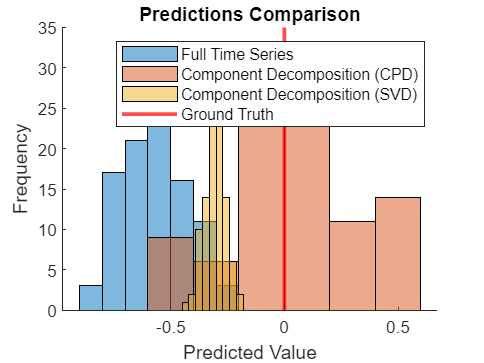


clear all;
addpath('./tensorlab');  % Ensure Tensorlab is in your path
addpath('./cvx');  % Ensure CVX is in your path

% Parameters
N = 100;  % Number of points in the time series
L = 20;   % Number of rows in each Hankel matrix
num_series = 3;  % Number of sinusoidal signals
num_experiments = 100;  % Number of experiments to perform
rank = 3;  % Rank for the CP decomposition

% Generate sinusoidal signals with optional exponential decay
t = (1:N)';
signal1 = sin(2 * pi * 0.1 * t) .* exp(-0.01 * t);
signal2 = sin(2 * pi * 0.05 * t) .* exp(-0.01 * t);
signal3 = sin(2 * pi * 0.02 * t) .* exp(-0.01 * t);

% Combine signals to form the time series matrix
time_series_matrix = [signal1, signal2, signal3];
time_series = signal1 + signal2 + signal3;  % For SVD method

% Ground truth for point 100
ground_truth = sum(time_series_matrix(N, :));

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_components_cpd = zeros(num_experiments, 1);
predictions_components_svd = zeros(num_experiments, 1);

% Define options for CPD
options = struct;
options.Display = 0;  % Turn off display

% Add noise to the time series and perform the experiment
for exp = 1:num_experiments
    % Add noise
    noisy_tensor = time_series_matrix + randn(size(time_series_matrix)) * 0.1;  % Adjust noise level as needed
    noisy_series = time_series + randn(N, 1) * 0.1;  % For SVD method

    % Full time series prediction using AR model for each series
    pred_full_sum = 0;
    for i = 1:num_series
        data = iddata(noisy_tensor(1:N-1, i), [], 1);
        ar_model = ar(data, 1);
        pred_full = predict(ar_model, data, 1);
        pred_full_sum = pred_full_sum + pred_full.OutputData(end);
    end
    predictions_full(exp) = pred_full_sum;

    % Construct 3D Hankel tensor
    H3D = zeros(L, N-L+1, num_series);
    for i = 1:num_series
        H2D = hankel(noisy_tensor(1:L, i), noisy_tensor(L:N, i));
        H3D(:, :, i) = H2D;
    end

    % Perform CP decomposition using Tensorlab
    cp_decomp = cpd(H3D, rank, options);

    % Predict each component separately using CPD
    pred_components_cpd_sum = 0;
    for comp = 1:rank
        component_data = iddata(cp_decomp{1}(:, comp), [], 1);
        ar_model_comp = ar(component_data, 1);
        pred_comp = predict(ar_model_comp, component_data, 1);
        pred_components_cpd_sum = pred_components_cpd_sum + pred_comp.OutputData(end);
    end
    predictions_components_cpd(exp) = pred_components_cpd_sum;

    % Decompose the time series into components using SVD
    [U, S, V] = svd(hankel(noisy_series(1:N-1)), 'econ');
    num_components = rank;
    components = U(:, 1:num_components) * S(1:num_components, 1:num_components) * V(:, 1:num_components)';

    % Predict each component separately using SVD
    pred_components_svd_sum = 0;
    for comp = 1:num_components
        model_comp = ar(components(:, comp), 1);  % AR(1) model for each component
        pred_comp = predict(model_comp, components(:, comp), 1);
        pred_components_svd_sum = pred_components_svd_sum + pred_comp(end);
    end
    predictions_components_svd(exp) = pred_components_svd_sum;
end

% Compare predictions in a single plot
figure;
hold on;
histogram(predictions_full, 'FaceAlpha', 0.5, 'DisplayName', 'Full Time Series');
histogram(predictions_components_cpd, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (CPD)');
histogram(predictions_components_svd, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (SVD)');
title('Predictions Comparison');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truth, 'r', 'LineWidth', 2, 'DisplayName', 'Ground Truth');  % Ground truth line
legend;
hold off;


% Display mean, median, and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp(['Mean: ', num2str(mean(predictions_full)), ', Median: ', num2str(median(predictions_full)), ', Std: ', num2str(std(predictions_full))]);

Mean: -0.56984, Median: -0.58018, Std: 0.14151



disp('Component Decomposition Predictions (SVD):');

Component Decomposition Predictions (SVD):


disp(['Mean: ', num2str(mean(predictions_components_svd)), ', Median: ', num2str(median(predictions_components_svd)), ', Std: ', num2str(std(predictions_components_svd))]);

Mean: -0.30294, Median: -0.30308, Std: 0.044463



disp('Component Decomposition Predictions (CPD):');

Component Decomposition Predictions (CPD):


disp(['Mean: ', num2str(mean(predictions_components_cpd)), ', Median: ', num2str(median(predictions_components_cpd)), ', Std: ', num2str(std(predictions_components_cpd))]);

Mean: 0.025679, Median: 0.074708, Std: 0.26404
